# finding the polytropic index from the profiles.

## read data


new_env(7);

zred = 0

CLUSTER = 'CL7'

units;

r500=get_rvir(500);
r200=get_rvir(200);

boxx=4;
rho=RHOG(boxx);
tmp=T(boxx);

rhoSphere=cart2sphere(rho);
tmpSphere=cart2sphere(tmp);

rp=(0.05:0.01:3).*r200;
[rhoP,~]=read_RHO_Profiles(rp);
tmpP=read_T_Profile(rp);
global hub
%pre=rho.*tmp;


## calculate median and average

len=length(rhoSphere);
rhoMean=zeros(1,len);
rhoMed=rhoMean;
rSum=rhoMean;

tmpMean=zeros(1,len);
tmpMed=tmpMean;
tSum=tmpMean;
for i=1:len
    arr=rhoSphere(i,:,:);
    arr=reshape(arr,[numel(arr) 1]);
   
    rhoMean(i)=mean(arr);
    rhoMed(i)=median(arr);
 
    arr=tmpSphere(i,:,:);
    arr=reshape(arr,[numel(arr) 1]);
   
    tmpMean(i)=mean(arr);
    tmpMed(i)=median(arr);
 
end

bin=boxx/hub/2/len;
rOut=(1:len).*bin;
rIn=rOut-bin;
rb=0.5.*(rIn+rOut);
shellVol=4*pi/3*(rOut.^3-rIn.^3);



## plot

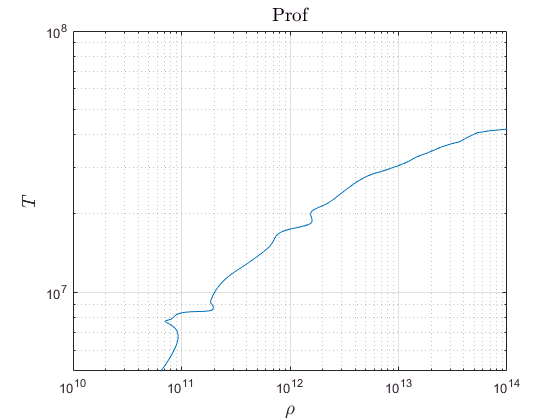

xl=[1e10 1e14];
yl=[5e6 1e8];


%% T vs rho 

figure
loglog(rhoP,tmpP)
xlim(xl);
ylim(yl)
xlabelmine('$\rho$')
ylabelmine('$T$')
titlemine('Prof')
grid

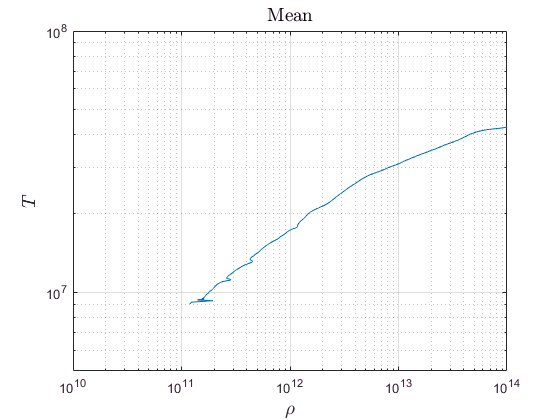



figure
loglog(rhoMean,tmpMean)
xlim(xl);
ylim(yl)
xlabelmine('$\rho$')
ylabelmine('$T$')
titlemine('Mean')
grid

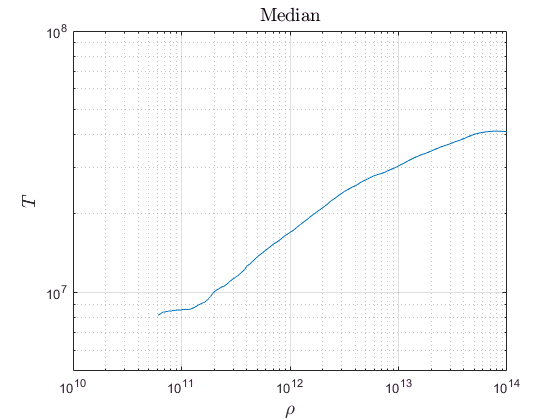


figure
loglog(rhoMed,tmpMed)
xlim(xl);
ylim(yl)
xlabelmine('$\rho$')
ylabelmine('$T$')
titlemine('Median')
grid

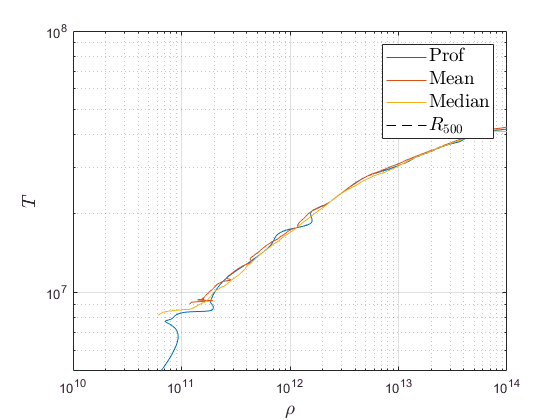


figure
h(1)=loglog(rhoP,tmpP,'DisplayName','Prof');
hold on
h(2)=loglog(rhoMean,tmpMean,'DisplayName','Mean');
h(3)=loglog(rhoMed,tmpMed,'DisplayName','Median');
grid
hl=legend(h);
set(hl,'Interpreter','latex','Fontsize',14)
xlim(xl);
ylim(yl)
xlabelmine('$\rho$')
ylabelmine('$T$')

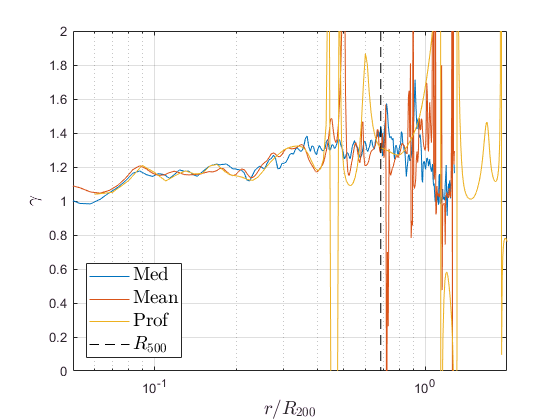

gamP=derive1(log10(tmpP),log10(rhoP))+1;
gamMean=derive1(log10(tmpMean),log10(rhoMean))+1;
gamMed=derive1(log10(tmpMed),log10(rhoMed))+1;

figure
h(1)=semilogx(rb(2:end-1)./r200,gamMed,'DisplayName','Med');
hold on
h(2)=semilogx(rb(2:end-1)./r200,gamMean,'DisplayName','Mean');
h(3)=semilogx(rp(2:end-1)./r200,gamP,'DisplayName','Prof');



h(4)=semilogx(r500./r200.*[1 1],[-2 2]','--k',...
    'DisplayName','$R_{500}$');
grid
xlim([0.05 2])
ylim([0 2])

hl=legend(h);
set(hl,'Interpreter','latex','Fontsize',14,'Location','SouthWest')

xlabelmine('$r/R_{200}$');
ylabelmine('$\gamma$')

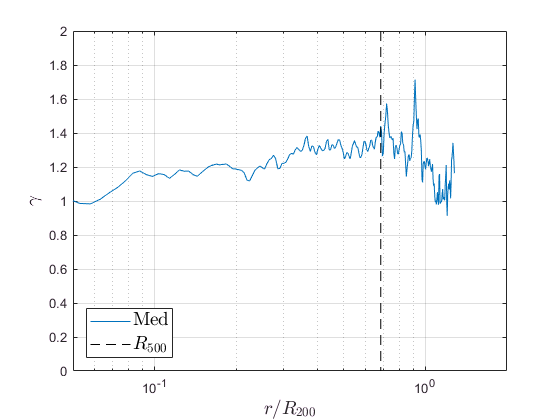



figure
%h(1)=semilogx(rp(2:end-1)./r200,gamP,'DisplayName','Prof');
%hold on
%h(2)=semilogx(rb(2:end-1)./r200,gamMean,'DisplayName','Mean');
h(3)=semilogx(rb(2:end-1)./r200,gamMed,'DisplayName','Med');
hold on
h(4)=semilogx(r500./r200.*[1 1],[-2 2]','--k',...
    'DisplayName','$R_{500}$');
grid
xlim([0.05 2])
ylim([0 2])

hl=legend(h(3:4));
set(hl,'Interpreter','latex','Fontsize',14,'Location','SouthWest')

xlabelmine('$r/R_{200}$');
ylabelmine('$\gamma$')

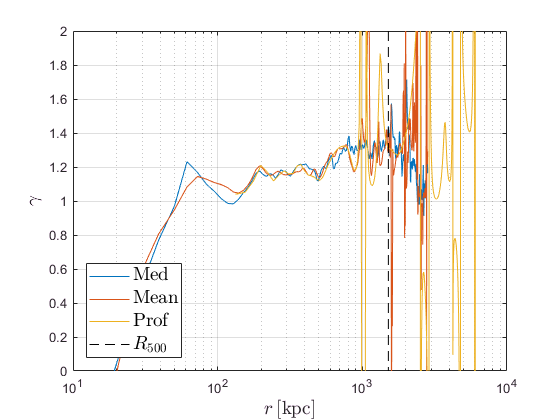



figure
h(1)=semilogx(1000.*rb(2:end-1),gamMed,'DisplayName','Med');
hold on
h(2)=semilogx(1000.*rb(2:end-1),gamMean,'DisplayName','Mean');
h(3)=semilogx(1000.*rp(2:end-1),gamP,'DisplayName','Prof');



h(4)=semilogx(1000.*r500.*[1 1],[-2 2]','--k',...
    'DisplayName','$R_{500}$');
grid

ylim([0 2])

hl=legend(h);
set(hl,'Interpreter','latex','Fontsize',14,'Location','SouthWest')

xlabelmine('$r\, [\mathrm{kpc}]$');
ylabelmine('$\gamma$')

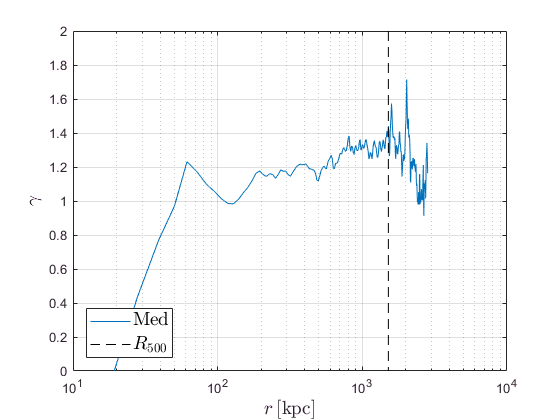



figure
%h(1)=semilogx(rp(2:end-1)./r200,gamP,'DisplayName','Prof');
%hold on
%h(2)=semilogx(rb(2:end-1)./r200,gamMean,'DisplayName','Mean');
h(3)=semilogx(1000.*rb(2:end-1),gamMed,'DisplayName','Med');
hold on
h(4)=semilogx(1000.*r500.*[1 1],[-2 2]','--k',...
    'DisplayName','$R_{500}$');
grid

ylim([0 2])

hl=legend(h(3:4));
set(hl,'Interpreter','latex','Fontsize',14,'Location','SouthWest')

xlabelmine('$r\, [\mathrm{kpc}]$');
ylabelmine('$\gamma$')